Demo_Basics_Spikes;

This is a live matlab script for demonstraing how to do basic plotting and analysis on spike data. 

This will show you how to plot PSTH and rasters and how to use ROC analysis scripts.

written by: Amirhossein Asadian @ Corneil Lab

Last edit: 27, March, 2025

Load Sample data

clc; clear; 

cd C:\Users\CorneilLab\Desktop\AA\Belle\Be231124

load('Z_Be231124_SC_Spikes.mat')
load('Z_Be231124_Analog.mat')
load('Z_Be231124_ML.mat')


First let's get rasters and spdn data for left and right target locations and plot the average firing rate

get_spikes_trial function helps you get spikes and spdn for trials you want

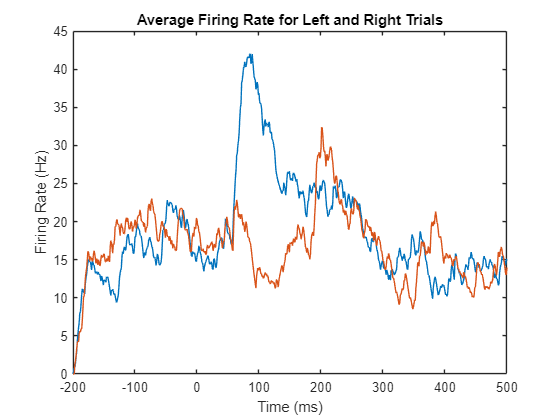

time_re_target = -200:500;

trs_right = find(Z_ML.condition == 5 & Z_ML.TrialError == 1 & strcmp(Z_ML.Target_Location(2,:),'Right'));
ch = 5;
unitID = 1;
spk = Z_Spikes.data(ch).neural_timeStamps(1, find(Z_Spikes.data(ch).neural_timeStamps(2, :) == Z_Spikes.data(ch).Units(unitID)));
[SPIKES_RIGHT, SPDEN_RIGHT] = get_spikes_trial(Z_Analog, spk, trs_right, 'PDnumber', 1, 'predur', -time_re_target(1), 'postdur', time_re_target(end));


trs_right = find(Z_ML.condition == 5 & Z_ML.TrialError == 1 & strcmp(Z_ML.Target_Location(2,:),'Left'));
ch = 5;
unitID = 1;
spk = Z_Spikes.data(ch).neural_timeStamps(1, find(Z_Spikes.data(ch).neural_timeStamps(2, :) == Z_Spikes.data(ch).Units(unitID)));
[SPIKES_LEFT, SPDEN_LEFT] = get_spikes_trial(Z_Analog, spk, trs_right, 'PDnumber', 1, 'predur', -time_re_target(1), 'postdur', time_re_target(end));


figure
plot(time_re_target, mean(SPDEN_RIGHT))
hold on
plot(time_re_target, mean(SPDEN_LEFT))
title('Average Firing Rate for Left and Right Trials')
ylabel('Firing Rate (Hz)')
xlabel('Time (ms)')

What if we want to plot spdn as patchplots and plot rasters on top of that? you can use plot_patchplot and plot_rasters_above function:

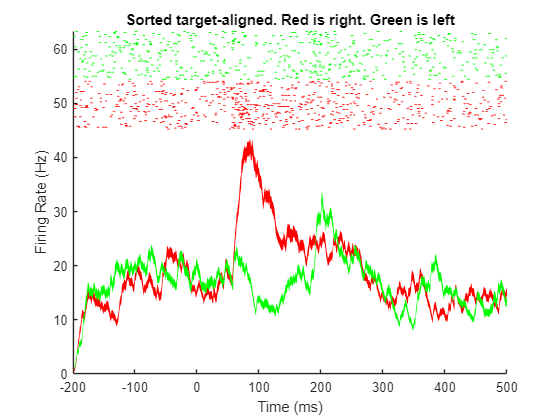

figure; hold on
plot_patchplot(time_re_target, SPDEN_RIGHT, 'r', 'Sorted target-aligned. Red is right. Green is left');
plot_patchplot(time_re_target, SPDEN_LEFT, 'g', '');

YAXIS = ylim;
yaxis_add = (YAXIS(2)-YAXIS(1))/5; % Rasters will add 20%
% plot_rasters_above function requires nan instead of zeros 
SPIKES_RIGHT(SPIKES_RIGHT == 0) = nan;
SPIKES_LEFT(SPIKES_LEFT == 0) = nan;
plot_rasters_above(SPIKES_RIGHT, 'r', yaxis_add);
plot_rasters_above(SPIKES_LEFT, 'g', yaxis_add);
ylabel('Firing Rate (Hz)')
xlabel('Time (ms)')

So what is the latency in these figures? We use ROC analysis:

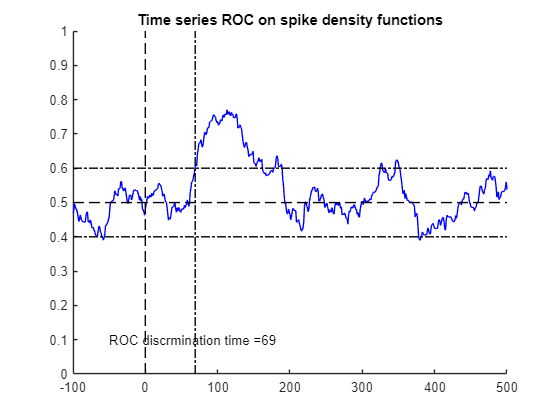

min_ROC_time = -100; max_ROC_time = 500;
ROC_time = min_ROC_time: max_ROC_time;
ROC = [];

for i = 1:length(ROC_time)
    colmatch = find(time_re_target == ROC_time(i));
    ROC(end+1,:) = [ROC_time(i), calcROC_BC(SPDEN_LEFT(:,colmatch), SPDEN_RIGHT(:,colmatch))];
end

figure; hold on; title('Time series ROC on spike density functions')
plot(ROC(:,1),ROC(:,2),'b-')
axis([min_ROC_time max_ROC_time 0 1])
plot([0 0],[0 1],'k--')
plot([min_ROC_time max_ROC_time],[.5 .5],'k--')
plot([min_ROC_time max_ROC_time],[.6 .6],'k-.')
plot([min_ROC_time max_ROC_time],[.4 .4],'k-.')
onset_latency = find_onset_latency_ROC(ROC_time,ROC(:,2),[30 100],[.6 8 10],0);
text(min_ROC_time + 50,0.1,strcat('ROC discrmination time =',num2str(onset_latency)));
plot([onset_latency onset_latency],[0 1],'k-.')

You can also detrend the ROC if you like (not necessarily good): 

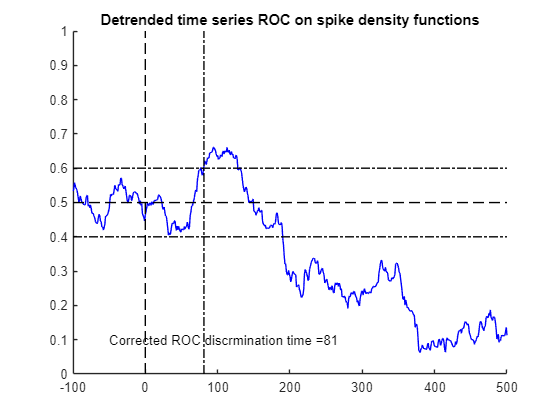

baseline_ROC_start_index = find(ROC_time == -100);
baseline_ROC_end_index = find(ROC_time == 30);
if ~isnan(onset_latency) & sum(ROC(baseline_ROC_start_index:baseline_ROC_end_index,2)) > 0
    % Then detrend the ROC from -100 to +30, replot, and
    % recalculate threshold
    R = linfit_jo(-100:30,ROC(baseline_ROC_start_index:baseline_ROC_end_index,2)');
    lineartrend = [];
    for x = min_ROC_time:max_ROC_time
        lineartrend(end+1) = R(1)*x+R(3)-0.5;   % to center it around 0.5
    end
    ROC_detrend = ROC(:,2)-lineartrend';

    figure; hold on; title('Detrended time series ROC on spike density functions')
    plot(ROC(:,1),ROC_detrend,'b-')
    axis([min_ROC_time max_ROC_time 0 1])
    plot([0 0],[0 1],'k--')
    plot([min_ROC_time max_ROC_time],[.5 .5],'k--')
    plot([min_ROC_time max_ROC_time],[.6 .6],'k-.')
    plot([min_ROC_time max_ROC_time],[.4 .4],'k-.')
    onset_latency_detrended = find_onset_latency_ROC(ROC_time,ROC_detrend,[30 100],[.6 8 10],0);
    if ~isnan(onset_latency)
        text(min_ROC_time + 50,0.1,strcat('Corrected ROC discrmination time =',num2str(onset_latency_detrended)));
        plot([onset_latency_detrended onset_latency_detrended],[0 1],'k-.')
    end

end